# 1 准备数据

先运行本节，再按顺序演示。这里只使用简单的数学数据。

clc,clear;
x = linspace(-2,2,21);
y = linspace(-2,2,21);
[X,Y] = meshgrid(x,y);
F = X.^2 + Y.^2;
U = -X;
W = -Y;

## 2 contour 画等值线

**2.1 设定等值线数量**

10 表示等值线数量

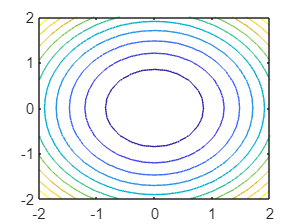

figure;
contour(X,Y,F,10);

**2.2 设定等值线的数值**

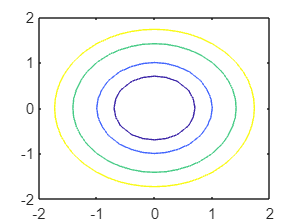

figure;
contour(X,Y,F,[0.5 1 2 3]);

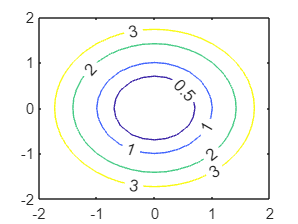

contour(X,Y,F,[0.5 1 2 3],'ShowText','on'); % 如果加上showtext则会显示数值

**2.3 只画一条等值线**

[2 2] 表示只画 F=2。

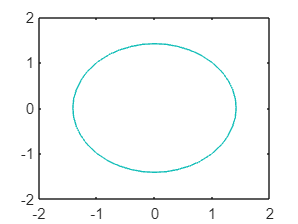

figure;
contour(X,Y,F,[2 2]);

## 3 quiver 画矢量场方向

画出来的是一个矢量场里各点的方向，如电场里的电场方向，磁场里的磁场方向

**参数含义**

quiver(X,Y,U,W)：X、Y 是位置，U、W 是横向和纵向分量。默认自动缩放箭头。

**3.1 起点-终点**

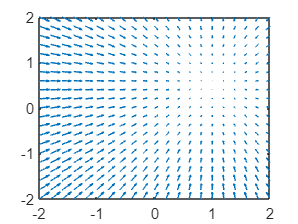

% 场中所有点指向终点(1,0.5)
U = 1 - X; 
W = 0.5 - Y;

figure;
quiver(X,Y,U,W);

% 可把上一行 quiver 改成 quiver(X,Y,U,W,0)，观察关闭缩放的效果。

**3.2 已知角度，画出方向**

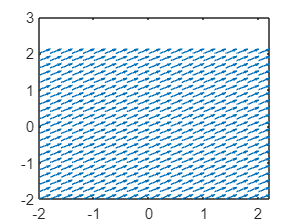

A = 0.2;
theta = 30;

U = A*cosd(theta)*ones(size(X));
W = A*sind(theta)*ones(size(Y));

figure;
quiver(X,Y,U,W);

**3.3 画电场例子**

在 (1,1) 放一个电荷量为 1 nC 的正点电荷，画出 X、Y 网格各点的电场。坐标单位为米。

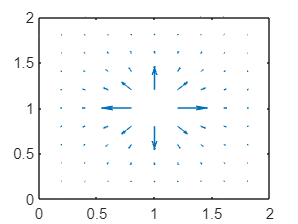

k = 9e9;
q = 1e-9;

R = sqrt((X-1).^2 + (Y-1).^2);
EX = k*q*(X-1)./R.^3;
EY = k*q*(Y-1)./R.^3;

figure;
quiver(X,Y,EX,EY);
xlim([0 2]);
ylim([0 2]);

## 4 streamline 

从指定位置出发，沿着向量场的方向，一步步追踪出来的连续曲线。如电场线，磁场线

- `quiver`：在各个网格点画箭头，显示当地的方向和大小。

- `streamline`：沿这些方向追踪，画出连续的路径。曲线上每一点的切线方向，都与当地向量方向一致。

它不是简单地把相邻箭头的端点连接起来。

**参数含义**

streamline(X,Y,EX,EY,xs,ys)：X、Y 是位置，EX、EY 是前面算出的电场分量，xs、ys 是电场线的追踪起点。

**为什么需要 **`xs、ys`**？**

因为一个向量场里可以画出无数条流线，xs, ys表示从哪些起点开始画线。

**起点选择**

**4.1 在电荷周围选十二个起点**

先运行 3.3 的电场计算。在以 (1,1) 为中心、半径 0.3 m 的圆周上选起点，避开电荷所在位置；红圈标出起点。

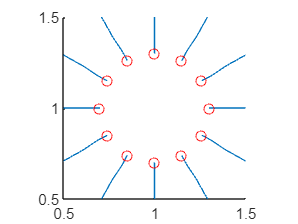

theta = (0:11)*2*pi/12;
xs = 1 + 0.3*cos(theta);
ys = 1 + 0.3*sin(theta);
figure;
streamline(X,Y,EX,EY,xs,ys);
hold on;
plot(xs,ys,'ro');
hold off;
axis equal;
xlim([0.5 1.5]);
ylim([0.5 1.5]);

**4.2 改成六个起点**

重新计算 xs、ys；电场线变少，但 EX、EY 没有改变。这里的正电荷使电场线从起点向外延伸。

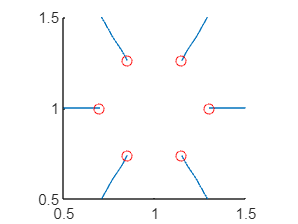

theta = (0:5)*2*pi/6;
xs = 1 + 0.3*cos(theta);
ys = 1 + 0.3*sin(theta);
figure;
streamline(X,Y,EX,EY,xs,ys);
hold on;
plot(xs,ys,'ro');
hold off;
axis equal;
xlim([0.5 1.5]);
ylim([0.5 1.5]);

## 5. 正负双电荷的电场举例

左边 (0.6,1) 为 +1 nC，右边 (1.4,1) 为 -1 nC。这个独立例子重新准备网格，按 6.1、6.2、6.3 顺序运行。

[X,Y] = meshgrid(linspace(0,2,81));
k = 9e9;
q = 1e-9;

R1 = sqrt((X-0.6).^2 + (Y-1).^2);
R2 = sqrt((X-1.4).^2 + (Y-1).^2);
R1(R1<0.04) = NaN;  % 略去电荷附近，避免奇异值
R2(R2<0.04) = NaN;

EX = k*q*(X-0.6)./R1.^3 - k*q*(X-1.4)./R2.^3;
EY = k*q*(Y-1)./R1.^3 - k*q*(Y-1)./R2.^3;

**5.1 在正电荷附近选起点 正向画**

先在正电荷周围选起点，沿 EX、EY 正向追踪。黑圈为起点，红色加号为正电荷，蓝色短横线为负电荷。有些场线离开网格后就无法继续追踪，因此负电荷外侧仍缺少曲线。

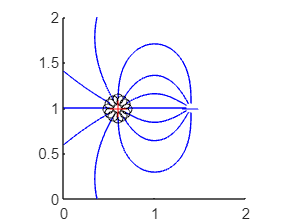

theta = (0:11)*2*pi/12;
xs1 = 0.6 + 0.1*cos(theta);
ys1 = 1 + 0.1*sin(theta);

figure;
h = streamline(X,Y,EX,EY,xs1,ys1);
set(h,'Color','b');
hold on;
plot(xs1,ys1,'ko');
plot(0.6,1,'r+',1.4,1,'b_','MarkerSize',10);
hold off;
axis equal;
xlim([0 2]); ylim([0 2]);

**5.2 在负电荷附近选起点 反向补画**

在右边负电荷的外侧半圆弧上另选一组起点 xs2、ys2，并用 -EX、-EY 反向追踪。蓝线保留原来的正向结果，红线补出右侧缺少的部分；这不是从中线同一组起点向两边画。

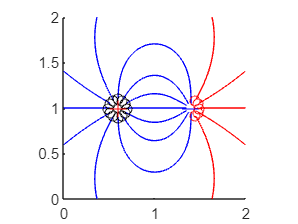

theta = (-60:30:60)*pi/180;
xs2 = 1.4 + 0.1*cos(theta);
ys2 = 1 + 0.1*sin(theta);

figure;
h = streamline(X,Y,EX,EY,xs1,ys1);     % 正电荷附近，正向
set(h,'Color','b');
hold on;
h = streamline(X,Y,-EX,-EY,xs2,ys2);  % 负电荷外侧，反向
set(h,'Color','r');
plot(xs1,ys1,'ko',xs2,ys2,'ro');
plot(0.6,1,'r+',1.4,1,'b_','MarkerSize',10);
hold off;
axis equal;
xlim([0 2]); ylim([0 2]);

关键是两组不同位置的起点：正电荷附近正向画，负电荷外侧反向补画。若负电荷附近也用 EX、EY 正向画，往往只得到朝向负电荷的一小截。实际电场方向仍由正电荷指向负电荷；近电荷的小空隙来自略去的奇异区域。此处采用答案的选点与追踪思路，电荷位置、电量和角度数量使用本课堂例子的设置。